%	Initialise script
Proj = currentProject;
cd(fullfile(Proj.RootFolder, "TicTacToe"));

%	Create environment
NumObs = 3^9;		%	Number of observation states (Pl 1, Pl 2 or empty in each grid position)
NumAct = 9;			%	Number of actions (3x3 grid)

OI = rlFiniteSetSpec(1:NumObs);		%	Observation Info
OI.Name = "Tic-Tac-Toe Observation States";

AI = rlFiniteSetSpec(1:NumAct);		%	Action Info
OI.Name = "Tic-Tac-Toe Actions";

env = rlFunctionEnv(OI, AI, @Step, @Reset);

%	Create QTable
%		Note that not all states are possible (e.g. all one counter or some multiple
%		3 in a row)
qTable = rlTable(OI, AI);
qRepresentation = rlQValueRepresentation(qTable, OI, AI);
qRepresentation.Options.LearnRate = .5;

%	Create Agent Options
agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .1;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 1e-2;
agentOpts.EpsilonGreedyExploration.EpsilonMin = 1e-3;
qAgent = rlQAgent(qRepresentation, agentOpts);

%	Set training options
trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 10;
trainOpts.MaxEpisodes= 1e4;
trainOpts.StopTrainingCriteria = "EpisodeCount";
trainOpts.StopTrainingValue = trainOpts.MaxEpisodes;
trainOpts.ScoreAveragingWindowLength = 10;
trainOpts.Plots = "None";

%	Train the agent
rng(0);
trainingStats = train(qAgent, env, trainOpts);
trainingStats.Information.ElapsedTime

ans = '230.59 sec'

return

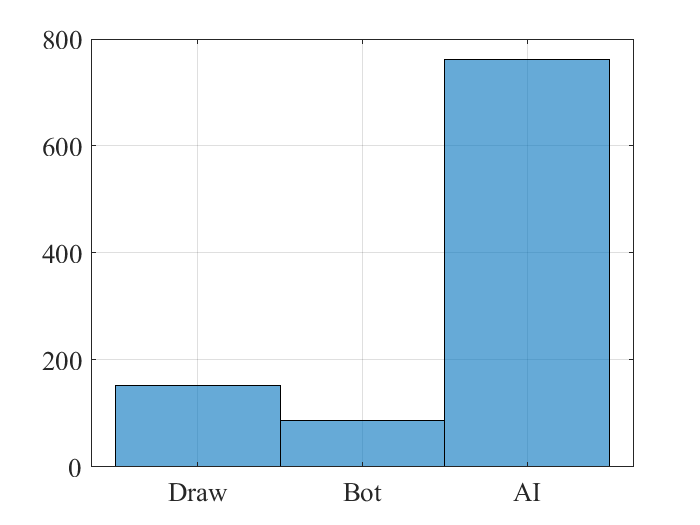

%	Compare AI v Bot
% load("TrainingData.mat", "qAgent");
obj = TicTacToe; 
w = []; 
for n=1:1000
	obj = obj.Reset; 
	P = randi(2); 
	W = obj.CheckWinner; 
	while ~W 
		if obj.CurrentPlayer==P
			obj = obj.Choose("Bot", true); 
		else
			[R, C] = ind2sub([3 3], getAction(qAgent, obj.GetState)); 
			if obj.Grid(R, C)
				break
			else
				obj = obj.Insert(R, C); 
			end
		end
		[W, Res] = obj.CheckWinner; 
	end
	w(n) = (W<0)*(-1-W) + (W>0)*(2 - (W==P)); 
end
histogram(w)
grid on;
set(gca, "XTick", -1:2, "XTickLabel", ["Illegal", "Draw", "Bot", "AI"])

## Reset function

Used to generate initial state and logged signals (Data)

function [InitState, Data] = Reset()
Algorithms = ["Random", "Bot"];

Data = struct( ...
	"Obj", TicTacToe, ...
	"Player", randi(2), ...
	"Algorithm", randsample(Algorithms, 1), ...
	"Options", {{}});

switch Data.Algorithm
	case "Bot"
		Data.Options = {logical(randi(2)-1)};
end

if Data.Player==2
	Data.Obj = Data.Obj.Choose(Data.Algorithm, Data.Options{:});
end

InitState = Data.Obj.GetState;
end


## Step Function

Used to generate the next step in the algorithm

%	Step by applying the action to the game board
function [State, Reward, IsDone, Data] = Step(Action, Data)
Rewards = struct( ...
	"Win", 20, ...
	"Draw", -5, ...
	"Lose", -20, ...
	"Illegal", -inf);

%	If currentplayer not changed, then return illegal move
if Data.Obj.Grid(Action)
	Result = nan;
else
	%	Attempt to insert counter in grid index Action
	[Row, Col] = ind2sub([3 3], Action);
	Data.Obj = Data.Obj.Insert(Row, Col);
	Result = Data.Obj.CheckWinner;
	if abs(Result)~=1
		Data.Obj = Data.Obj.Choose(Data.Algorithm, Data.Options{:});
		Result = Data.Obj.CheckWinner;
	end
end

switch Result
	case Data.Player
		Reward = Rewards.Win;
	case 3-Data.Player
		Reward = Rewards.Lose;
	case -1
		Reward = Rewards.Draw;
	case 0
		Reward = sum(Data.Obj.CalculateScores.^3) * (3-2*Data.Player)/10;
	otherwise
		Reward = Rewards.Illegal;
end
if isfinite(Result) && logical(Result)
	IsDone = true;
else
	IsDone = false;
end

State = Data.Obj.GetState;
end
